## 0. Initialization

**Cleaning the environment**

clear; close all; clc;

**Installation and import**

Download and unzip the content of the folder `'LoopDetect_for_Matlab'`. Within the MATLAB session, navigate to this folder and work there or add the path of the folder to MATLAB's search path for the current MATLAB session by MATLAB's `addpath()` function. Deending on where you stored the folder, its name could be something like `'/Users/Desktop/LoopDetect' `on Mac or `'C:\matlab\LoopDetect'` on Windows.

% Retrieve the LoopDetect folder location when having navigated to the folder
% within the MATLAB session.
LoopDetect_Folder_Name = fullfile(pwd, '..', 'LoopDetect_2025', 'src', 'loopdetect_for_matlab');
LoopDetect_Folder_Name = char(java.io.File(LoopDetect_Folder_Name).getCanonicalPath); % normalize path
addpath(LoopDetect_Folder_Name);

**Models:**

Models = fullfile(pwd, '..', 'LoopDetect_2025', 'src', 'models');
Models = char(java.io.File(Models).getCanonicalPath); % normalize path
addpath(Models);

## 1. Model

This model for complex formation (4 species) is already implemented with the name as `BIOMD0000000009-matlab` and `func_huang96_biomod_p1` and `func_huang96_biomod_p2`, provided respectively by BioModels and Prof. Baum, saved in the path for models as above.

In case there is any fixes, new code will be implemented below:

## 2. Result reproduction

Parameters set original:

% Parameters from supplementary material
x0=zeros(26,1);
x0(1) = 3.0E-5;
x0(2) = 3.0E-4;
x0(3) = 0.003;
x0(4) = 0.0;
x0(5) = 1.2;
x0(6) = 0.0;
x0(7) = 0.0;
x0(8) = 1.2;
x0(9) = 0.0;
x0(10) = 0.0;
x0(11) = 0.12;
x0(12) = 3.0E-4;
x0(13) = 0.0;
x0(14) = 0.0;
x0(15) = 0.0;
x0(16) = 0.0;
x0(17) = 0.0;
x0(18) = 0.0;
x0(19) = 0.0;
x0(20) = 0.0;
x0(21) = 0.0;
x0(22) = 0.0;
x0(23) = 0;
x0(24) = 0;
x0(25) = 0;
x0(26) = 0;

s_star = x0';  % Initial concentrations

### Temporal dynamics 1 - Original initial states

Solving the ODE model to observe temporal dynamics

Intial stimulation to stablize the system

tspan = linspace(0, 1100, 1101);
opts = odeset('RelTol',1e-6,'AbsTol',1e-9);  % closer to typical SciPy accuracy
[t,sol] = ode15s(@(t,x) func_huang96_biomod_p1(t,x), tspan, x0, opts);
s_star_2=sol(end,:); %the last point of the simulation is chosen

Plot

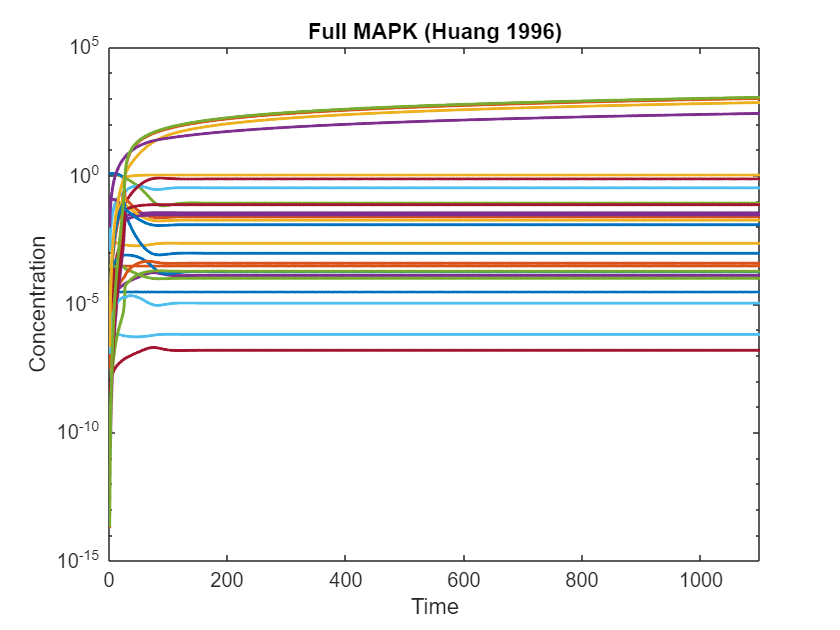

figure;
semilogy(t, sol, 'LineWidth', 1.5);
%xline(t_perb, '--', 'LineWidth', 1.5);
xlabel('Time');
ylabel('Concentration');
xlim([0,1100]);
title('Full MAPK (Huang 1996)');

Loop detect at t=1100

loop_rep = find_loops_vset(@(x)func_huang96_biomod_p1(1100,x),sol(end,:)',1000);
disp(loop_summary(loop_rep{1}));

                length_1    length_2    length_3    length_4    length_5    length_6    length_7    length_8    length_9
                ________    ________    ________    ________    ________    ________    ________    ________    ________

    total          22          30          24          17          26          19          16          22          12   
    negative       22           0          24           0          26           0          16           0          12   
    positive        0          30           0          17           0          19           0          22           0   



### Temporal dynamics 2 - Oscillation behavior

Try another sets of initial values (2):

x0=zeros(26,1);
x0(1) = 1.0E-7;
x0(2) = 1.2115E-4;
x0(3) = 3.7122E-3;
x0(4) = 0.0;
x0(5) = 4.0658;
x0(6) = 0.0;
x0(7) = 0.0;
x0(8) = 2;
x0(9) = 0.0;
x0(10) = 0.0;
x0(11) = 7.5372E-2;
x0(12) = 9.4579E-5;
x0(13) = 0.0;
x0(14) = 0.0;
x0(15) = 0.0;
x0(16) = 0.0;
x0(17) = 0.0;
x0(18) = 0.0;
x0(19) = 0.0;
x0(20) = 0.0;
x0(21) = 0.0;
x0(22) = 0.0;
x0(23) = 0;
x0(24) = 0;
x0(25) = 0;
x0(26) = 0;

s_star = x0';  % Initial concentrations

Solving the ODE model to observe temporal dynamics

Intial stimulation to stablize the system

tspan = linspace(0, 1100, 1101);
opts = odeset('RelTol',1e-6,'AbsTol',1e-9);  % closer to typical SciPy accuracy
[t,sol] = ode15s(@(t,x) func_huang96_biomod_p1(t,x), tspan, x0, opts);
s_star_2=sol(end,:); %the last point of the simulation is chosen

Plot

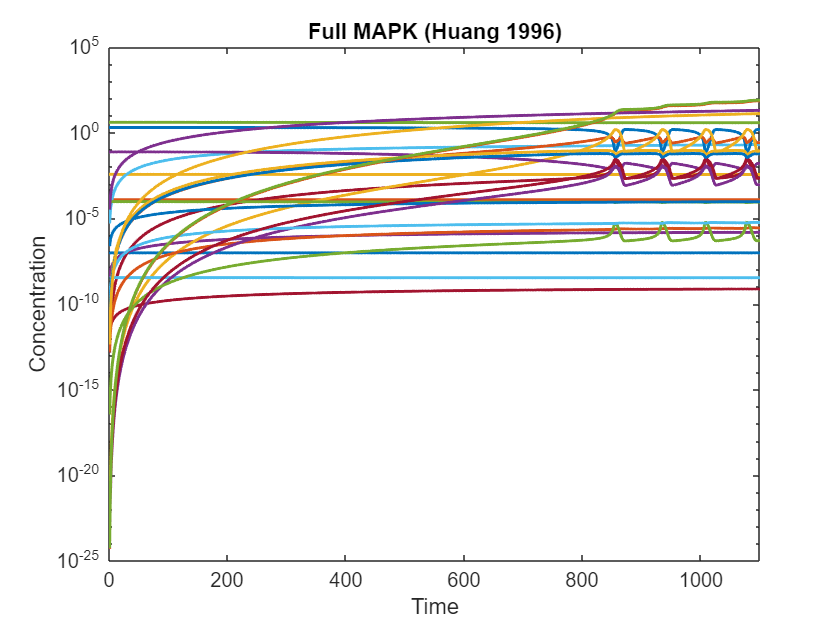

figure;
semilogy(t, sol, 'LineWidth', 1.5);
xlabel('Time');
ylabel('Concentration');
xlim([0,1100]);
title('Full MAPK (Huang 1996)');

legend()

Investigate loop at final time point for this second set of parameters:

loop_rep = find_loops_vset(@(x)func_huang96_biomod_p1(1100,x),sol(end,:)',1000);
disp(loop_summary(loop_rep{1}));

                length_1    length_2    length_3    length_4    length_5    length_6    length_7    length_8    length_9
                ________    ________    ________    ________    ________    ________    ________    ________    ________

    total          22          30          24          17          26          19          16          22          12   
    negative       22           0          24           0          26           0          16           0          12   
    positive        0          30           0          17           0          19           0          22           0   



y0 = s_star_2(:);

Now, draw temporal dynamics for unstimulated conditions from t=[-1000, 0], and then stimulated conditions from t=[0, 300].

tspan = linspace(0, 7900, 7901);
[t, sol] = ode15s(@(t,x) func_huang96_biomod_p1(t,x), tspan, s_star_2, opts);
s_star_3=sol(end,:);
tspan = linspace(0, 300, 301);
[t, sol] = ode15s(@(t,x) func_huang96_biomod_p1(t,x), tspan, s_star_3, opts);

Plot

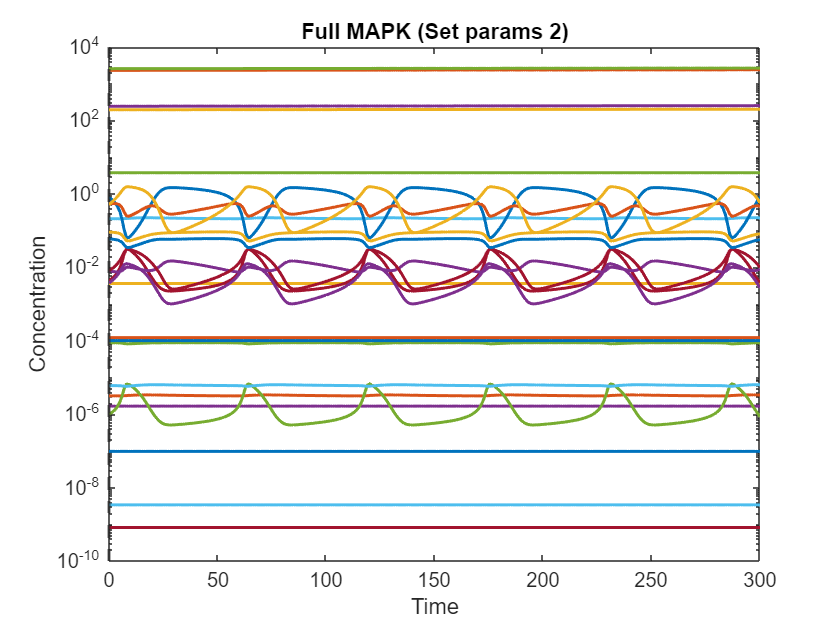

figure;
semilogy(t, sol, 'LineWidth', 1.5);
xline(0, '--', 'LineWidth', 1.5);
xlabel('Time');
ylabel('Concentration');
xlim([0,300]);
title('Full MAPK (Set params 2)');
hold off;

Extract only interested variables to plot:

investigate_label = {'E1 (S1)', 'MAPKK** (S7)', 'MAPK** (S10)'};
investigate_index = [1, 7, 10];

Plot:

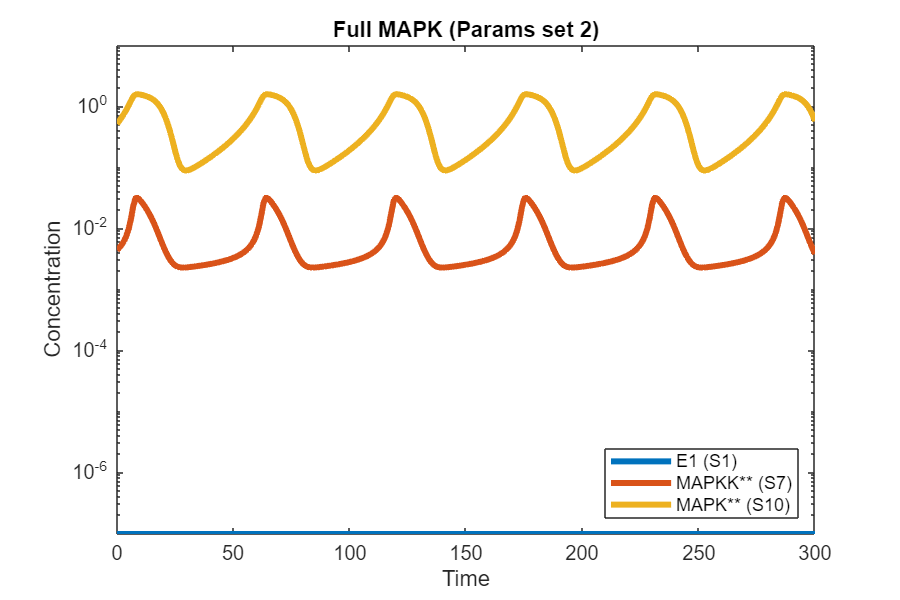

figure('Position',[100 100 600 400]);
hold on
for i = 1:numel(investigate_index)
    plot(t, sol(:, investigate_index(i)), 'LineWidth', 3, ...
        'DisplayName', investigate_label{i});
end
set(gca, 'YScale', 'log')
hold off

xlim([0, 300]);
xticks(0:50:300);

ylim([0, 10]);
%yticks(0:50:250);

xlabel('Time');
ylabel('Concentration');
title('Full MAPK (Params set 2)');
legend('Location','southeast');  % similar to Python legend outside
box on

[loop_rep, loop_rep_index, jac_rep, jac_rep_index] = find_loops_vset(@(x)func_huang96_biomod_p1(1100,x),sol',1000);
disp(loop_rep)

    {188×3 table}



### Temporal dynamics 3 (at 2 different steady states) - Use biomod_p2

Try another sets of initial values (3) - Steady states 1:

x0=zeros(26,1);
x0(1) = 7.9433E-5;
x0(2) = 3.283E-4;
x0(3) = 9.2235E-4;
x0(4) = 0.0;
x0(5) = 5.1288*49/100;
x0(6) = 5.1288/2;
x0(7) = 5.1288/100;
x0(8) = 8.1552E-1 - 0.1; 
x0(9) = 0.0;
x0(10) = 0.1;
x0(11) = 5.0345E-1;
x0(12) = 2.1238E-4;
x0(13) = 0.0;
x0(14) = 0.0;
x0(15) = 0.0;
x0(16) = 0.0;
x0(17) = 0.0;
x0(18) = 0.0;
x0(19) = 0.0;
x0(20) = 0.0;
x0(21) = 0.0;
x0(22) = 0.0;
x0(23) = 0;
x0(24) = 0;
x0(25) = 0;
x0(26) = 0;

s_star = x0';  % Initial concentrations

Solving the ODE model to observe temporal dynamics

Intial stimulation to stablize the system

tspan = linspace(0, 1, 1001);
opts = odeset('RelTol',1e-6,'AbsTol',1e-9);  % closer to typical SciPy accuracy
[t2,sol2] = ode15s(@(t,x) func_huang96_biomod_p2(t,x), tspan, x0, opts);

Try another sets of initial values (4) - Steady states 2:

x0=zeros(26,1);
x0(1) = 7.9433E-5;
x0(2) = 3.283E-4;
x0(3) = 9.2235E-4;
x0(4) = 0.0;
x0(5) = 5.1288/3;
x0(6) = 5.1288/2;
x0(7) = 5.1288/6;
x0(8) = 8.1552E-1 - 0.1; 
x0(9) = 0.0;
x0(10) = 0.1;
x0(11) = 5.0345E-1;
x0(12) = 2.1238E-4;
x0(13) = 0.0;
x0(14) = 0.0;
x0(15) = 0.0;
x0(16) = 0.0;
x0(17) = 0.0;
x0(18) = 0.0;
x0(19) = 0.0;
x0(20) = 0.0;
x0(21) = 0.0;
x0(22) = 0.0;
x0(23) = 0;
x0(24) = 0;
x0(25) = 0;
x0(26) = 0;

s_star = x0';  % Initial concentrations

Solving the ODE model to observe temporal dynamics

Intial stimulation to stablize the system

tspan = linspace(0, 1, 1001);
[t1,sol1] = ode15s(@(t,x) func_huang96_biomod_p2(t,x), tspan, x0, opts);

Extract only interested variables to plot:

investigate_label = {'E1 (S1)', 'MAPKK** (S7)', 'MAPK** (S10)'};
investigate_index = [1, 7, 10];

Plot:

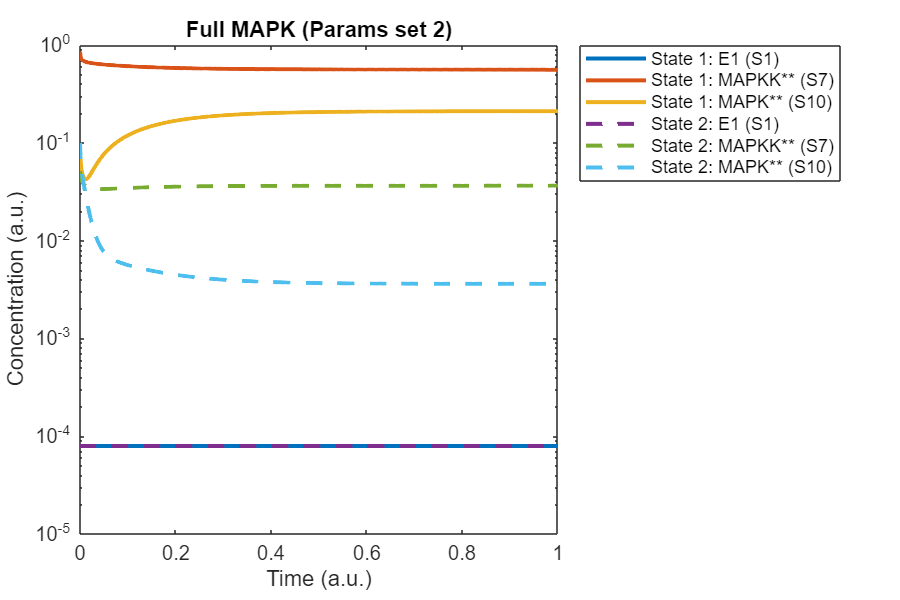

figure('Position',[100 100 600 400]);
hold on
for i = 1:numel(investigate_index)
    plot(t1, sol1(:, investigate_index(i)), 'LineWidth', 2, ...
         'DisplayName', sprintf('State 1: %s', investigate_label{i}));
end
for i = 1:numel(investigate_index)
    plot(t2, sol2(:, investigate_index(i)), 'LineWidth', 2, ...
         'LineStyle', '--', ...
         'DisplayName', sprintf('State 2: %s', investigate_label{i}));
end
set(gca, 'YScale', 'log')
hold off

xlim([0, 1]);
xticks(0:0.2:1);

%ylim([0, 10]);
%yticks(0:50:250);

xlabel('Time (a.u.)');
ylabel('Concentration (a.u.)');
title('Full MAPK (Params set 2)');
legend('Location','northeastoutside');  % similar to Python legend outside
box on

Plot

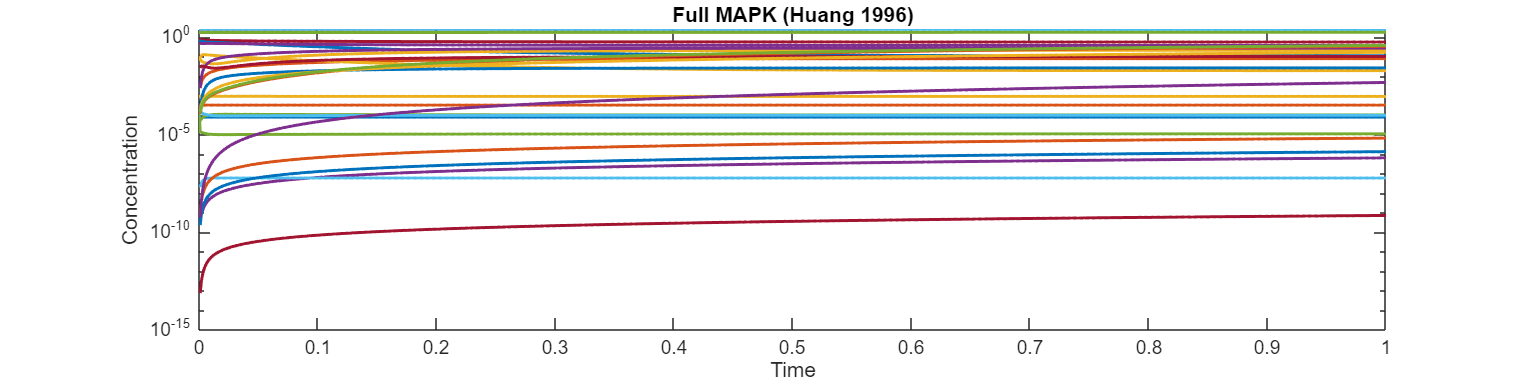

figure('Position',[100 100 1200 300]);
semilogy(t1, sol1, 'LineWidth', 1.5);
%xline(t_perb, '--', 'LineWidth', 1.5);
xlabel('Time');
ylabel('Concentration');
xlim([0,1]);
title('Full MAPK (Huang 1996)');
hold off;

### **Detect loop structure change:**

[loop_rep1, loop_rep_index1, jac_rep1, jac_rep_index1] = find_loops_vset(@(x)func_huang96_biomod_p2(1100,x),sol1',1000);
disp(loop_rep1)

    {68×3 table}    {188×3 table}




[loop_rep2, loop_rep_index2, jac_rep2, jac_rep_index2] = find_loops_vset(@(x)func_huang96_biomod_p2(1100,x),sol2',1000);
disp(loop_rep2)

    {68×3 table}    {188×3 table}



sel_idx   = [1 7 10];
sel_label = {'E1 (S1)', 'MAPKK** (S7)', 'MAPK** (S10)'};

% Safety: make sure indices are valid
assert(all(sel_idx >= 1 & sel_idx <= size(sol1,2)), 'sel_idx out of range.');

% Extract selected trajectories (time x selected_states)
sol_sel = sol1(:, sel_idx);

loop_id = loop_rep_index1(:);
disp('loop_rep_index and time_vec must match.'); disp(numel(loop_id)); disp(numel(t1));

loop_rep_index and time_vec must match.
        1001

        1001



% Find segment boundaries where loop_id changes
change_idx = [1; find(diff(loop_id) ~= 0) + 1; numel(loop_id) + 1];

nSeg = numel(change_idx) - 1;
t_start = zeros(nSeg,1);
t_end   = zeros(nSeg,1);
seg_id  = zeros(nSeg,1);

for s = 1:nSeg
    i1 = change_idx(s);
    i2 = change_idx(s+1) - 1;
    t_start(s) = t1(i1);
    t_end(s)   = t1(i2);
    seg_id(s)  = loop_id(i1);
end

transition_times = t_end(1:end-1);


Plot:

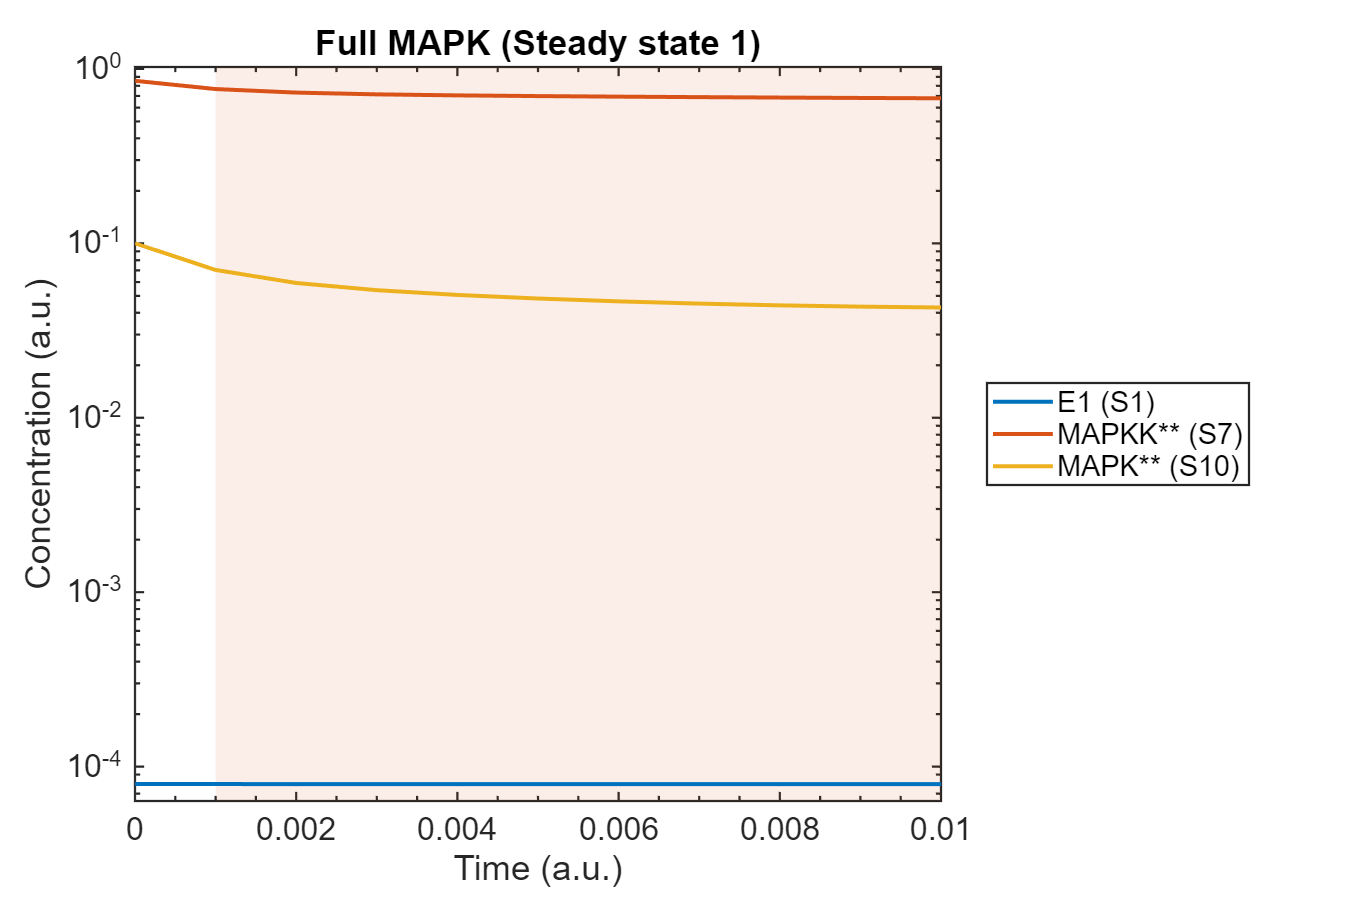

figure('Color','w', 'Position',[100 100 900 600]); hold on;

% Set x-limits early (so patches cover the right region)
xlim([0 0.01]); 
xlabel('Time (a.u.)');
ylabel('Concentration (a.u.)');
title('Full MAPK (Steady state 1)');

set(gca,'YScale','log')

% Get y-limits from data, then draw patches spanning full height
%ymin = -1; % min(sol(:));
%ymax = max(sol1(:))*1.1;
min_positive = min(sol1(sol1>0));
%ymin = min_positive * 0.5;      % slightly below smallest positive value
%ymax = max(sol1(:)) * 1.2;

%ylim([ymin ymax]);

min_val = min(sol_sel(sol_sel > 0));
max_val = max(sol_sel(:));

ylim([min_val*0.8  max_val*1.2])

% Colors for loop structures (categorical palette)
uID = unique(seg_id, 'stable');
cmap = lines(numel(uID));  % quick palette; swap to brewermap if you prefer

% Background bands (behind lines): patch rectangles
for s = 1:nSeg
    cidx = find(uID == seg_id(s), 1);
    x = [t_start(s) t_end(s) t_end(s) t_start(s)];
    y = [ymin ymin ymax ymax];   % must all be > 0
    patch(x, y, cmap(cidx,:), ...
        'EdgeColor','none', ...
        'FaceAlpha',0.10, ...
        'HandleVisibility','off');
end

% Vertical transition lines
for tt = transition_times(:)'
    xline(tt, '-', ...
        'Color', [0.3 0.3 0.3], ...
        'LineWidth', 0.7, ...
        'Alpha', 0.35, ...
        'HandleVisibility','off');
end

% Trajectories (only for selected params)
nSel = numel(sel_idx);
spec_colors = lines(nSel);
h = gobjects(nSel,1);

for j = 1:nSel
    h(j) = plot(t1, sol_sel(:,j), 'LineWidth', 2, 'Color', spec_colors(j,:));
end


% Axis ticks like your ggplot scale_x_continuous
%xticks(0:0.2:1);
%xlim([0 1]);

% Styling similar to theme_minimal + border
set(gca, ...
    'FontSize', 16, ...
    'Box', 'on', ...
    'LineWidth', 1.1, ...
    'XMinorTick', 'on');
grid off;

% Legend for species (like scale_colour_manual)
legend(h, sel_label, 'Location','eastoutside');

### **Jacobian matrix:**

j_0_un = numerical_jacobian_complex(@(x)func_varusai15_s4_fix(1, x, klin, knonlin_unstimulated),s_star_2);
signed_j_0_un =sign(j_0_un)

j_0_sti = numerical_jacobian_complex(@(x)func_varusai15_s4_fix(1, x, klin, knonlin_stimulated),sol_stimulated(end,:));
signed_j_0_sti =sign(j_0_sti)

## Export *.mlx to *.md / *.pdf

path = export("MATLAB/model_4_MAPK_full.mlx", "MATLAB/model_4_MAPK_full.pdf")

path = 'MATLAB\model_4_MAPK_full.pdf'

mdfile = export("MATLAB/model_4_MAPK_full.mlx","MATLAB/model_4_MAPK_full.md", Format="markdown", EmbedImages=true, ...
    AcceptHTML=true)

mdfile = 'MATLAB\model_4_MAPK_full.md'